
--- PID Controller Performance ---
Rise Time:     0.00 s (Target: < 1.0s)
Overshoot:     0.00% (Target: < 10%)
Settling Time: 0.00 s
----------------------------------


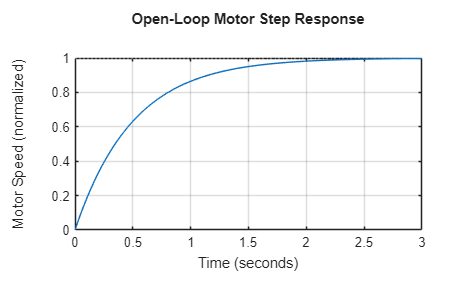

% PHASE 5: Comparison Plot
run('plant_model');

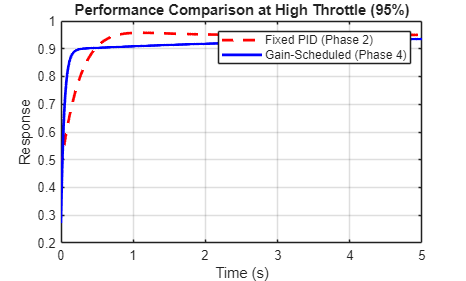


% Fixed PID (Phase 2)
C_fixed = pid(5, 10, 0.5);
T_fixed = feedback(C_fixed*G, 1);

% Aggressive Setpoint (to show the difference)
sp_high = 0.95; 

% Gain Scheduled (Phase 4 Logic)
C_sched = pid(15, 4, 0.2); 
T_sched = feedback(C_sched*G, 1);

% Simulate both
[y1, t1] = step(sp_high * T_fixed, 5);
[y2, t2] = step(sp_high * T_sched, 5);

% Plot
figure(5);
plot(t1, y1, 'r--', 'LineWidth', 2); hold on;
plot(t2, y2, 'b', 'LineWidth', 2);
grid on;
legend('Fixed PID (Phase 2)', 'Gain-Scheduled (Phase 4)');
title('Performance Comparison at High Throttle (95%)');
xlabel('Time (s)'); ylabel('Response');

saveas(gcf, 'results/comparison_plot.png');